addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\ExtractClouds");
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\CoarseAlignment");
addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\DataAnalysis\");

%load("afterICP.mat");
load("C:\Users\agori\Documents\MATLAB\MSc\P3processing-clean\Pancake3_Before_Clean\P3rawExtract.mat")

ICPtforms = readTformFile("C:\Users\agori\Documents\MATLAB\MSc\P3processing-clean\Pancake3_After_Clean\TrafoPrmOrigin.txt");

arrAfterICP=arrCloudTrans;
arrAfterICProtate=arrCloudTrans;
%apply ICPtforms
for k=1:8
    arrAfterICP(k)=pctransform(arrCloudTrans(k),ICPtforms(k));
    %correct entire with floorA
    arrAfterICProtate(k)=pctransform(arrAfterICP(k), floorTforms{1,1});
end

totalICP=pccat(arrAfterICProtate);

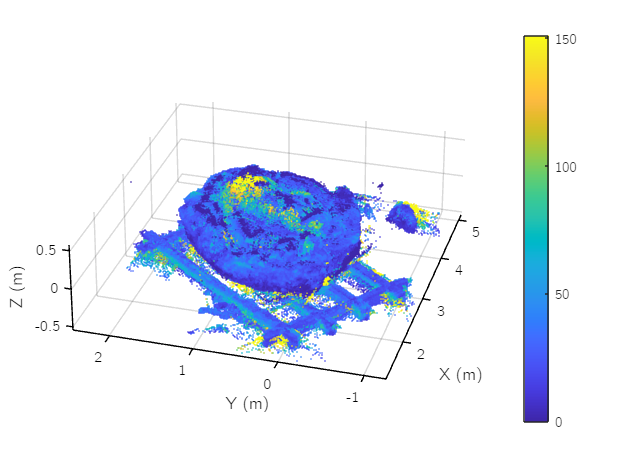

pcDisplay(totalICP.Location,totalICP.Intensity);
colorbar;

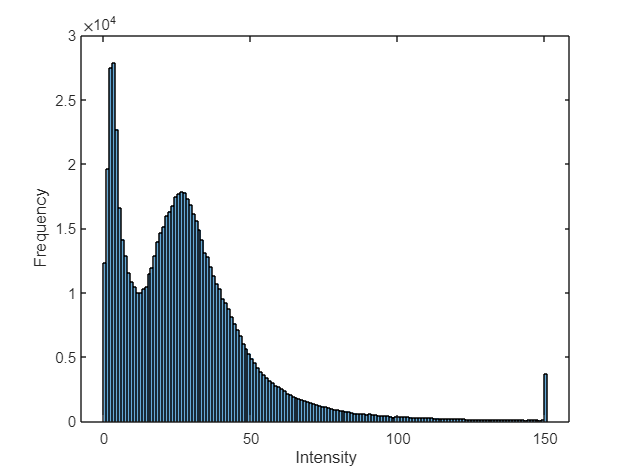

figure;
set(gca, 'FontName', 'CMU Bright');
histogram(totalICP.Intensity);
    ylabel('Frequency');
    xlabel('Intensity');

%Filter Intensities
arrIntensityFilt=arrAfterICProtate;
for k=1:8
    arrIntensityFilt(k)=filterIntensityCloud(arrAfterICProtate(k),0,140);
end



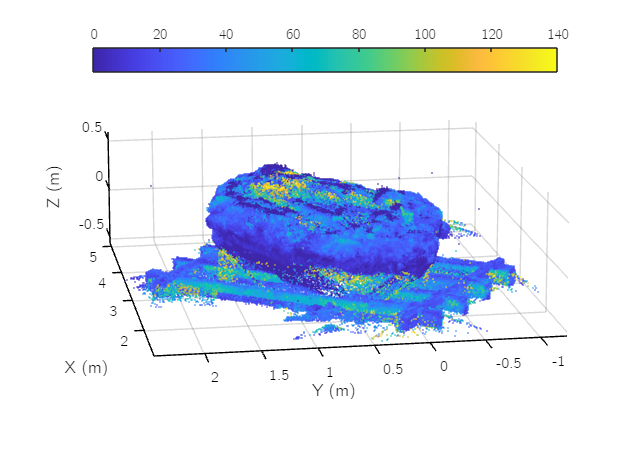

figure
set(gca,'fontname','CMU Bright')  % Set it to times
pcDisplay(totalInt.Location, totalInt.Intensity);
c = colorbar('Location','north'); % move below the plot
%c.TickDirection = 'out';         % makes ticks visible outside the bar
c.AxisLocation = 'out';          % moves ticks to the top side
view([-99.605 14.344])

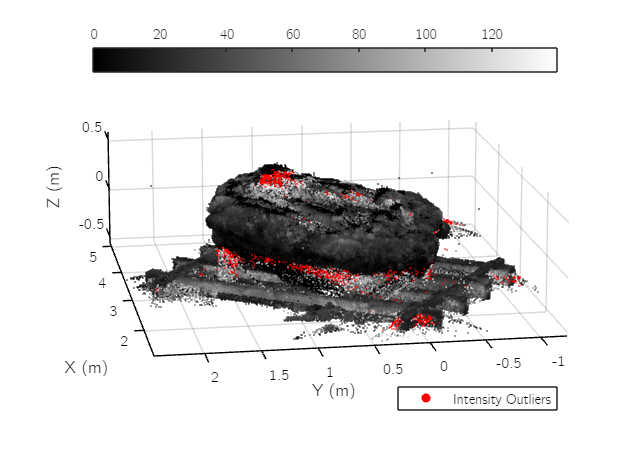


% Assume totalICP is a pointCloud with an Intensity field
I = totalICP.Intensity;
pts = totalICP.Location;

% Threshold
thresh = 140;

% Logical masks
lowMask = I < thresh;
highMask = I >= thresh;

% Separate points
ptsLow = pts(lowMask, :);
ilow=I(lowMask,:);
ptsHigh = pts(highMask, :);



% Display
figure;
%view([-73.8056026442575 28.8574342589771]);

% Set background color to white
%fig.Color = 'white';
%pcDisplay(ptsLow, [0 0 1]);   % blue for low intensities
pcDisplay(ptsLow, ilow);  
hold on;
pcDisplay(ptsHigh, [1 0 0]);    % red for high intensities
h1 = scatter3(nan, nan, nan, 60, [0 0 1], 'filled');
h2 = scatter3(nan, nan, nan, 60, [1 0 0], 'filled');
legend(h2, {'Intensity Outliers'}, ...
       'Location', 'southeast', ...
       'Orientation', 'vertical');


% Optional: Enable grid if not already on
grid on;
%legend boxoff
%title('Point Cloud by Intensity Threshold');
hold off;
colormap("gray")
c = colorbar('Location','north'); % move below the plot
%c.TickDirection = 'out';         % makes ticks visible outside the bar
c.AxisLocation = 'out'; 
view([-99.605 14.344])

tic
[arrFiltered,arrOutliers] = overlapFilter(arrIntensityFilt);
toc

Elapsed time is 1541.970260 seconds.


totalFilt=pccat(arrFiltered);
%pcDisplay(totalFilt);

filterTest=totalFilt;
outlierTest=pccat(arrOutliers);

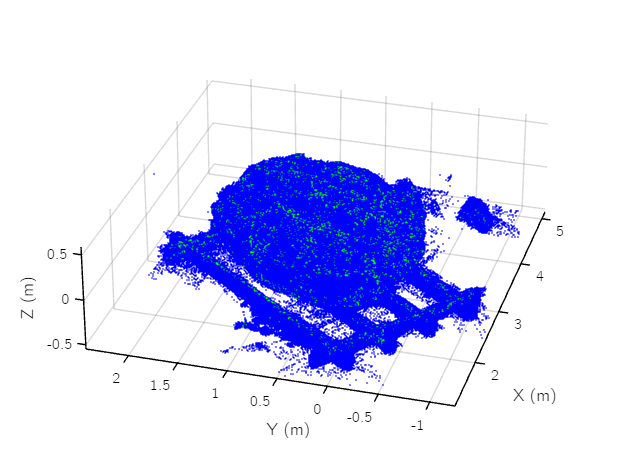

filterCol = pointCloud(filterTest.Location, 'Color', repmat(uint8([0, 255, 0]), size(filterTest.Location, 1), 1));
outlierCol=pointCloud(outlierTest.Location, 'Color', repmat(uint8([0, 0, 255]), size(outlierTest.Location, 1), 1));
pcDisplay(filterCol);
hold on
pcDisplay(outlierCol);
hold off

save("FilteredP3Clean.mat","arrIntensityFilt","arrOutliers","arrFiltered","arrAfterICProtate");